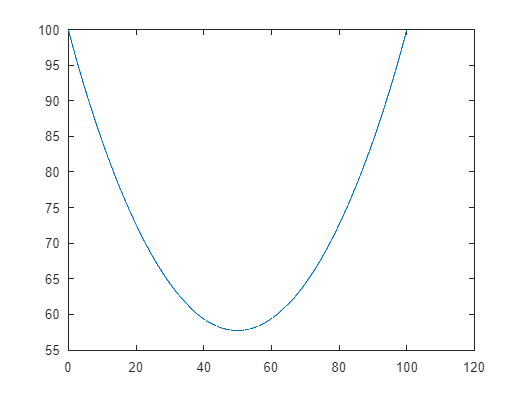

%24/02/2024 matrix computation adaptation, reducing line count by ~10x
order = 7;
%Position
%Control Points
P1 = [0,100];
P2 = P1;
P3 = P1;
P4 = P1;
P5 = P1;
P6 = [50,0];
P7 = [100,100];
P8 = P7;
P9 = P8;
P10 = P9;
P11 = P10;
CP = [P1; P2; P3; P4; P5; P6; P7; P8; P9; P10; P11];
DP = CP;
%Curve Parameters
pmin = 0;
pmax = 60;
pstep = 0.01;
%Knot Vector
kn1 = pmin;
kn2 = kn1 + pstep;
kn3 = kn1 + 2*pstep;
kn4 = kn1 + 3*pstep;
kn5 = kn1 + 4*pstep;
kn6 = kn1 + 5*pstep;
kn7 = kn1 + 6*pstep;
kn8 = pmax/5;
kn9 = 2*pmax/5;
kn10 = 3*pmax/5;
kn11 = 4*pmax/5;
kn12 = pmax - 6*pstep;
kn13 = pmax - 5*pstep;
kn14 = pmax - 4*pstep;
kn15 = pmax - 3*pstep;
kn16 = pmax - 2*pstep;
kn17 = pmax - pstep;
kn18 = pmax;
knot = [kn1, kn2, kn3, kn4, kn5, kn6, kn7, kn8, kn9, kn10, kn11, kn12, kn13, kn14, kn15, kn16, kn17, kn18];
validpmin = kn7;
validpmax = kn12;
NK2MAT = [];
NK3MAT = [];
NK4MAT = [];
NK5MAT = [];
NK6MAT = [];
NK7MAT = [];
PosMAT = [];
pM1 = [];
pM2 = [];
pM3 = [];
pM4 = [];
pM5 = [];
pM6 = [];
PosMAT = evaluate(CP, pmin, pstep, pmax, validpmin, validpmax, knot, order);
order = 6;
CP = DCP(CP, knot, order);
knot = Dkn(knot);
VelMAT = evaluate(CP, pmin, pstep, pmax, validpmin, validpmax, knot, order);
VMagMAT = absBS(VelMAT);
order = 5;
CP = DCP(CP, knot, order);
knot = Dkn(knot);
AccMAT = evaluate(CP, pmin, pstep, pmax, validpmin, validpmax, knot, order);
AMagMAT = absBS(AccMAT);
order = 4;
CP = DCP(CP, knot, order);
knot = Dkn(knot);
JerkMAT = evaluate(CP, pmin, pstep, pmax, validpmin, validpmax, knot, order);
JMagMAT = absBS(JerkMAT);
order = 3;
CP = DCP(CP, knot, order);
knot = Dkn(knot);
SnapMAT = evaluate(CP, pmin, pstep, pmax, validpmin, validpmax, knot, order);
SMagMAT = absBS(SnapMAT);
plot(PosMAT(:,1),PosMAT(:,2))

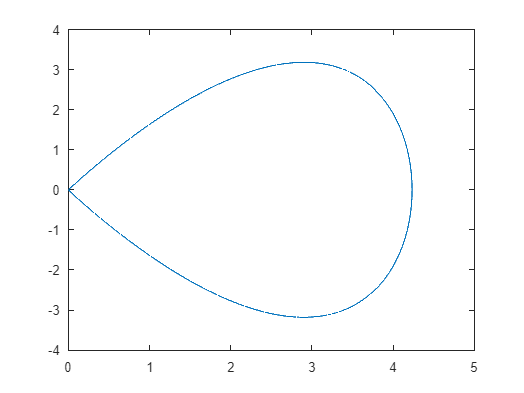

plot(VelMAT(:,1),VelMAT(:,2))

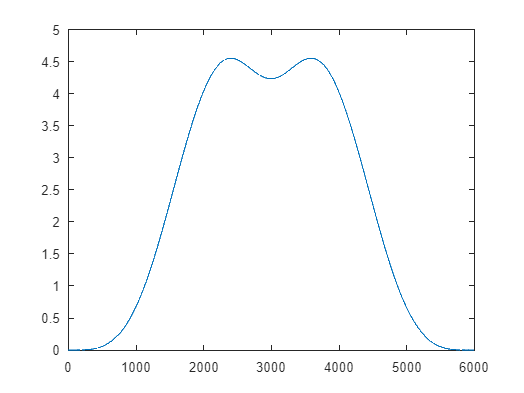

plot(VMagMAT(:,1), VMagMAT(:,2))

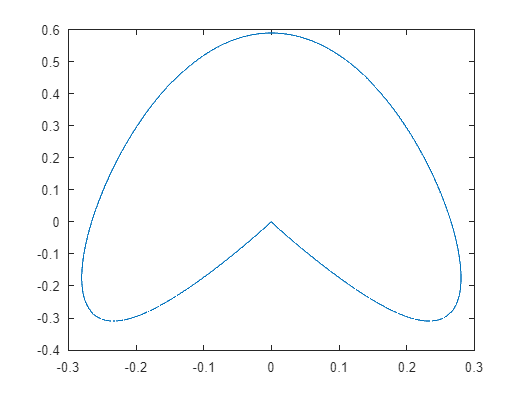

plot(AccMAT(:,1),AccMAT(:,2))

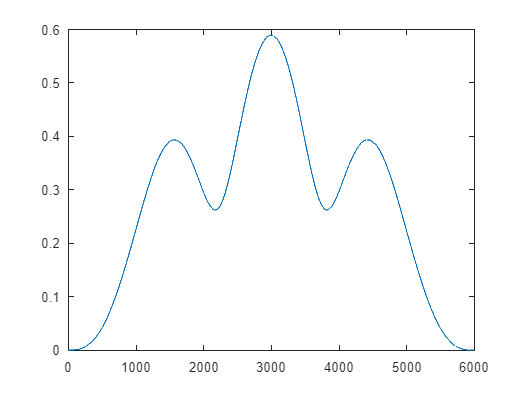

plot(AMagMAT(:,1), AMagMAT(:,2))

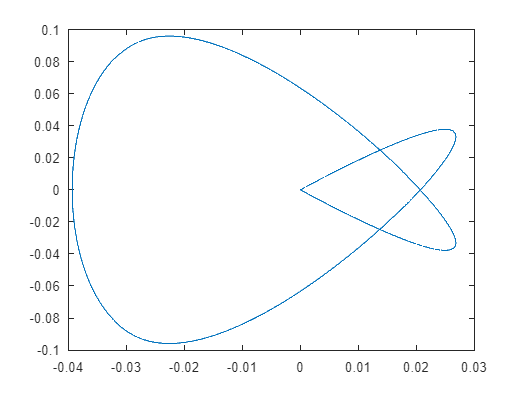

plot(JerkMAT(:,1),JerkMAT(:,2))

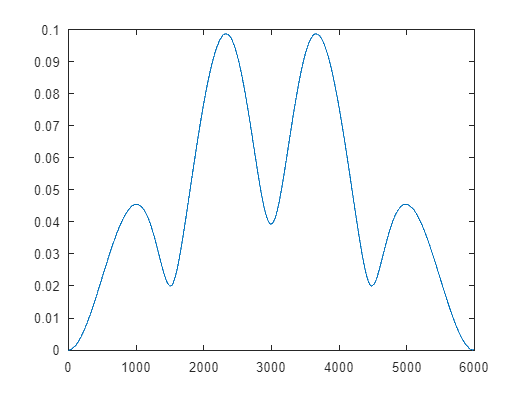

plot(JMagMAT(:,1), JMagMAT(:,2))

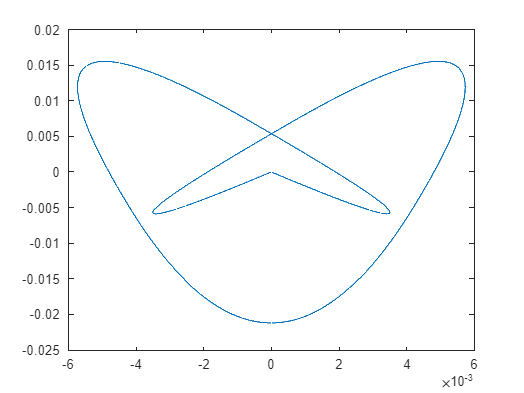

plot(SnapMAT(:,1),SnapMAT(:,2))

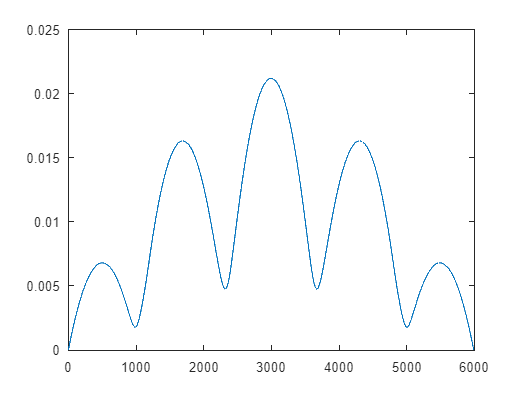

plot(SMagMAT(:,1), SMagMAT(:,2))

function pMAT = pMAT(p,knot,k)
    N = length(knot);
    pMAT = [];
    for i = 1:1:N-k
        pconst1 = (p-knot(1,i))/(knot(1,i+k-1)-knot(1, i));
        pconst2 = (knot(1,i+k)-p)/(knot(1,i+k)-knot(1,i+1));
        Head = zeros(i-1,1);
        Foot = zeros(N-k-i,1);
        pvect = [Head; pconst1; pconst2; Foot];
        pMAT = [pMAT, pvect];
    end
end
function CP = points(targets, order)
    P = height(targets);
    rep = order - 2;
    CP = [];
    hold = [targets(1,1), targets(1,2)];
    for n = 1:1:rep
        CP = [CP; hold];
    end
    for i = 2:1:P-1
        hold = [targets(i,1), targets(i,2)];
        CP = [CP; hold];
    end
    hold = [targets(P,1), targets(P,2)];
    for k = 1:1:rep
        CP = [CP; hold];
    end
end
function Knot = knotvect(CP, order, pmin, pmax, pstep)
    P = height(CP);
    K = P + order;
    Knot = pmin;
    for i = 1:1:order-1
        Knot = [Knot, pmin+i*pstep];
    end
    for i = 1:1:K-2*order-1
        Knot = [Knot, i*pmax/(K-2*order)];
    end
    for i = 1:1:order
        Knot = [Knot, pmax-(order-i)*pstep];
    end
end
function NK1MAT = NK1MAT(p, knot)
    N = length(knot);
    NK1MAT = [];
    for i = 1:1:N-1
        lowkn = knot(i);
        highkn = knot(i+1);
        if lowkn<=p && p<highkn
            NK1MAT = [NK1MAT, 1];
        else
            NK1MAT = [NK1MAT, 0];
        end
    end
end

function BSplineMAT = evaluate(CP, pmin, pstep, pmax, validpmin, validpmax, knot, order)
    BSplineMAT = [];
    for p = pmin:pstep:pmax
        if p >= validpmin
            if p<=validpmax
                k = 2;
                NK2MAT = NK1MAT(p, knot)*pMAT(p, knot, k);
                k = 3;
                NK3MAT = NK2MAT*pMAT(p, knot, k);
                k = 4;
                if order < k
                    Pos = NK3MAT*CP;
                else
                    NK4MAT = NK3MAT*pMAT(p, knot, k);
                    k = 5;
                    if order < k
                        Pos = NK4MAT*CP;
                    else
                        NK5MAT = NK4MAT*pMAT(p, knot, k);
                        k = 6;
                        if order < k
                            Pos = NK5MAT*CP;
                        else
                            NK6MAT = NK5MAT*pMAT(p, knot, k);
                            k = 7;
                            if order < k
                                Pos = NK6MAT*CP;
                            else
                                NK7MAT = NK6MAT*pMAT(p, knot, k);
                                Pos = NK7MAT*CP;
                            end
                        end
                    end
                end
                BSplineMAT = [BSplineMAT; Pos];
            end
        end
    end
end

function DP = DCP(CP, knot, k)
    n = length(CP);
    DP = [];
    for i = 1:1:n-1
        I = i+1;
        P1 = [CP(i,1),CP(i,2)];
        P2 = [CP(i+1,1),CP(i+1,2)];
        DPnew = (P2-P1)*k/(knot(I+k)-knot(I));
        DP = [DP; DPnew];
    end
end
function DKnot = Dkn(knot)
    N = length(knot);
    DKnot = [];
    for i = 1:1:N-2
        DKnew = knot(i+1);
        DKnot = [DKnot, DKnew];
    end
end
function MagMAT = absBS(Pos)
    N = length(Pos.');
    MagMAT = [];
    for i = 1:1:N
        X = Pos(i,1);
        Y = Pos(i,2);
        abs = sqrt(X^2+Y^2);
        MagMAT = [MagMAT; i, abs];
    end
end